%%1번
f = @(x) hym_25011970_func_1(x);

% 1) 근 찾기
a = fzero(f, 0)

a = 0


% 2) 최소값 찾기
x = fminbnd(f, 0, 4)

x = 0.7101

f_1 = f(x)

f_1 = -0.7757


%f(x)는 [0, 4]에서 연속함수이므로 최소값은 극값 또는 경계값에서 발생 -> f(0), f(4), f(극값)을 비교하고 이 중
%가장 작은 값이 최소값이다. 따라서 f(극값)이 최소값이다.

%%2번
h = 100;
v0 = 50;
g = 9.81;

t = hym_25011970_func_2(h, v0, g)

t =     7.4612    2.7324



t1 = t(1);
t2 = t(2);
%t1: 상승 중 해당 높이에 도달하는 시간
%t2: 하강 중 다시 해당 높이에 도달하는 시간

%% 3번
global V
V = 10;

f = @(r) hym_25011970_func_3(r);

% 표면적을 최소화하는 반지름
r_min = fminbnd(f, 0.01, 10)

r_min = 1.8901

A_min = f(r_min)

A_min = 19.4393


% 높이
h_min = 3*V/(pi*r_min^2)

h_min = 2.6730


% 최소값보다 10% 증가한 면적
t = 1.1 * A_min;

g = @(r) hym_25011970_func_3(r) - t;

% 좌우 경계 찾기
r1 = fzero(g, [0.01, r_min]);%왼
r2 = fzero(g, [r_min, 10]);%오

% 최적값에서 얼마나 벗어날 수 있는지
left = r_min - r1

left = 0.4078

right = r2 - r_min

right = 0.4415

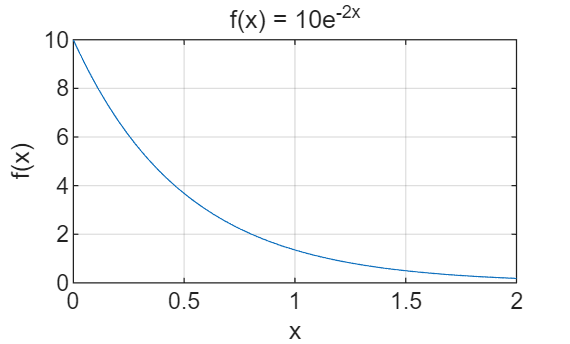


%% 4번

% 익명함수 생성
f = @(x) 10*exp(-2*x);

x = linspace(0, 2, 400);

y = f(x);

figure;
plot(x, y);
grid on;
xlabel('x');
ylabel('f(x)');
title('f(x) = 10e^{-2x}');

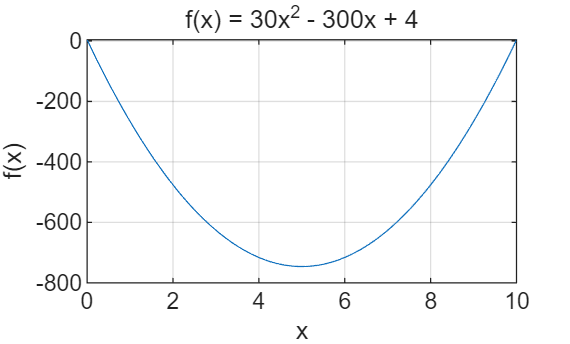


%%5번
%(a)
f = @(x) 30*x.^2 - 300*x + 4;

x = linspace(0, 10, 400);

y = f(x);

figure;
plot(x, y);
grid on;
xlabel('x');
ylabel('f(x)');
title('f(x) = 30x^2 - 300x + 4');


%(b)
xmin = fminbnd(f, 0, 10)

xmin = 5.0000

fmin = f(xmin)

fmin = -746

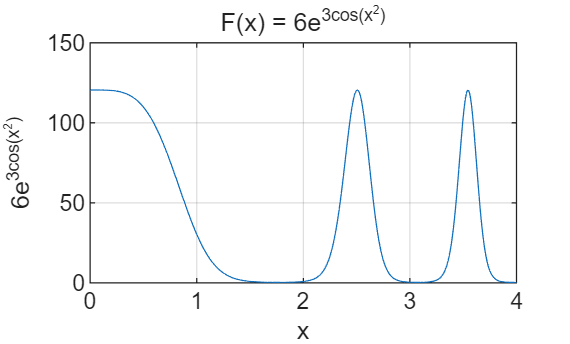


%%6번

f = @(x) x.^2;
g = @(y) 3*cos(y);
h = @(z) 6*exp(z);

F = @(x) h(g(f(x)));

x = linspace(0, 4, 400);
y = F(x);

figure;
plot(x, y);
grid on;
xlabel('x');
ylabel('6e^{3cos(x^2)}');
title('F(x) = 6e^{3cos(x^2)}');